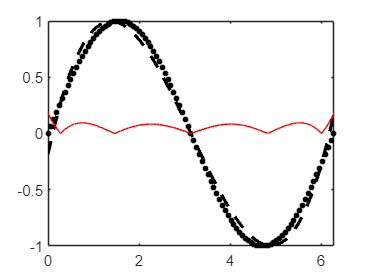

clear all;
close all;
clc;

%generat sample signal
nt = 101;
t= linspace(0,2*pi,nt);
f= sin(t);

%polyfit reconstruction coefficients
degree = 3;
coef_rec=polyfit(t,f,degree);

%t range
nt_rec=1001;
t_fit=linspace(min(t),max(t),nt_rec);

%polynomial values
f_rec=polyval(coef_rec,t_fit);

%error
f_ana=interp1(t,f,t_fit);
err=abs(f_rec-f_ana);

%plot
figure(1)
plot(t,f,'ko','MarkerSize',3,'MarkerFaceColor','k')
hold on
plot(t_fit,f_rec,'--k','LineWidth',2)
hold on
plot(t_fit,err,'-r')